# raincloud plots in Matlab

## First, we'll set up our path and use the colorbrewer function to define some nice color palettes:

% Path to save figures to
figdir = './img';   
if ~exist('figdir', 'dir')
    mkdir(figdir);
end

% Colours
try
    % get nice colours from colorbrewer
    % (https://uk.mathworks.com/matlabcentral/fileexchange/34087-cbrewer---colorbrewer-schemes-for-matlab)
    [cb] = cbrewer('qual', 'Set3', 12, 'pchip');
catch
    % if you don't have colorbrewer, accept these far more boring colours
    cb = [0.5 0.8 0.9; 1 1 0.7; 0.7 0.8 0.9; 0.8 0.5 0.4; 0.5 0.7 0.8; 1 0.8 0.5; 0.7 1 0.4; 1 0.7 1; 0.6 0.6 0.6; 0.7 0.5 0.7; 0.8 0.9 0.8; 1 1 0.4];
end

cl(1, :) = cb(4, :);
cl(2, :) = cb(1, :);

fig_position = [200 200 600 400]; % coordinates for figures

## Now we’ll generate some datapoints with similar means and standard deviations; the first is drawn from a random normal distribution and the second from a random exponential distribution. We’ll plot these same data repeatedly in different ways further down:

n = 250;

% set a random number generator seed for reproducible results
rng(123)

d{1} = [exprnd(5, 1, n) + 15]';
d{2} = [(randn(1, n) *5) + 20]';

means = cellfun(@mean, d);
variances = cellfun(@std, d);


## Let’s create a quick bar graph of these data. This is the kind of standard visualization you see in many papers, depicting the mean of the data plus standard deviation:

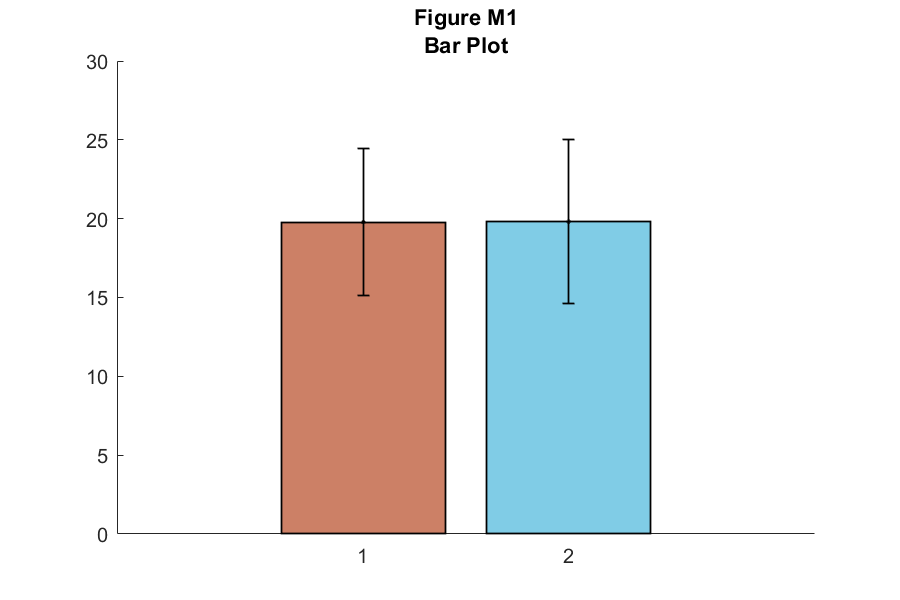

f1 = figure('Position', fig_position); hold on;
h = bar(means, 'FaceColor', 'flat', 'LineWidth', .9);

h(1).CData(1, :) = cl(1, :);
h(1).CData(2, :) = cl(2, :);

e = errorbar(1:2, means, variances, '.k', 'LineWidth', .9);
set(gca, 'XTick', 1:2);
title(['Figure M1' newline 'Bar Plot']);

% save
print(f1, fullfile(figdir, '1bar.png'), '-dpng');

## As you can see, this tells you something about the data, but a lot of really useful and important information is hidden such as the ‘shape’ or distribution of the data and the raw observations themselves. A histogram nicely shows some of what we’re missing:

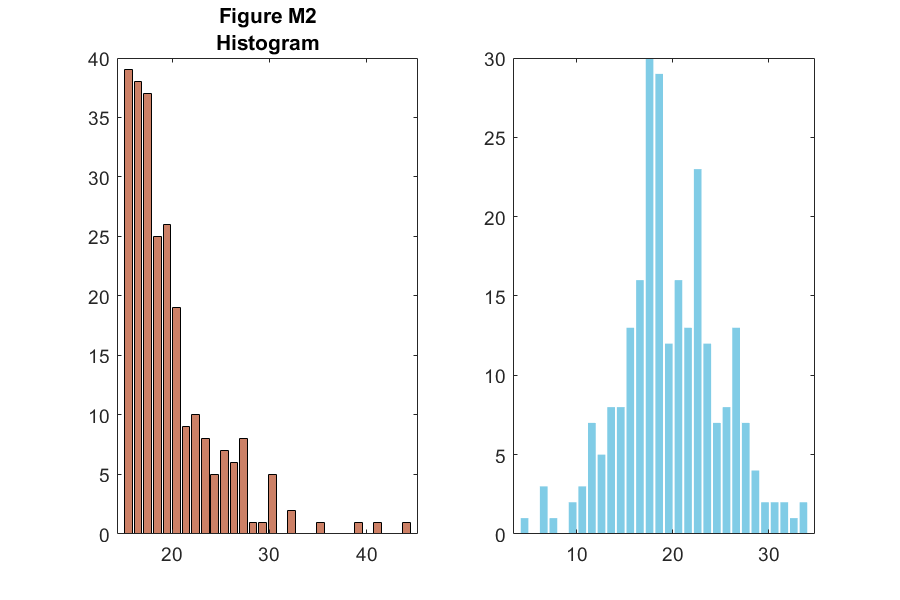

f2 = figure('Position', fig_position);
subplot(1, 2, 1)
[n1, x1] = hist(d{1}, 30);
bar(x1, n1, 'FaceColor', cl(1, :), 'EdgeColor', 'k');
title(['Figure M2' newline 'Histogram']);
subplot(1, 2, 2)
[n2, x2] = hist(d{2}, 30);
bar(x2, n2, 'FaceColor', cl(2,:), 'EdgeColor', 'none');

% save
print(f2, fullfile(figdir, '2hist.png'), '-dpng');

## However, now we’ve lost the summary data. The raincloud plot tries to bring these elements together in one intuitive plot. You can use the ‘raincloud_plot.m’ function accompanying this tutorial to produce these plots in Matlab:

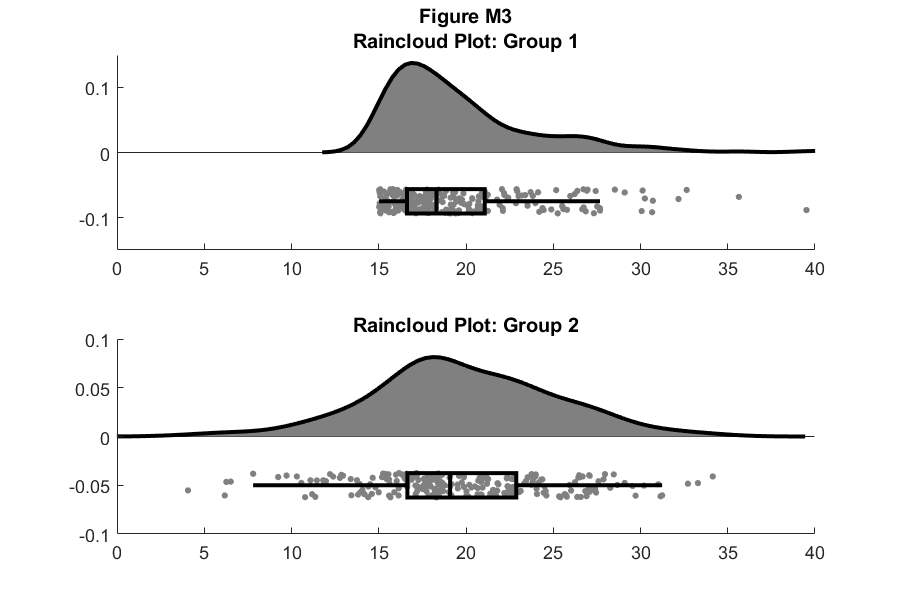

f3 = figure('Position', fig_position);
subplot(2, 1, 1)
h1 = raincloud_plot(d{1}, 'box_on', 1);
title(['Figure M3' newline 'Raincloud Plot: Group 1']);
set(gca, 'XLim', [0 40]);
box off
subplot(2, 1, 2)
h2 = raincloud_plot(d{2}, 'box_on', 1);
title('Raincloud Plot: Group 2');
set(gca, 'XLim', [0 40]);
box off

% save
print(f3, fullfile(figdir, '3Rain1.png'), '-dpng');

## This gives us the distribution (probability density plot), summary data (box plot), and raw observations all in one place. Now we’ll walk you through some of the options of the function, which you can use to change various aesthetic properties of the plot. The function only requires a vector of the data you want to plot as the input. Additionally, there are a variety of optional flags you can call to turn the boxplots on and off, to alter ('dodge') the position of the boxes and dots, and to change various aesthetics such as linewidth, colors, and so on. For example, by setting a few different flags we can create more colorful plots:

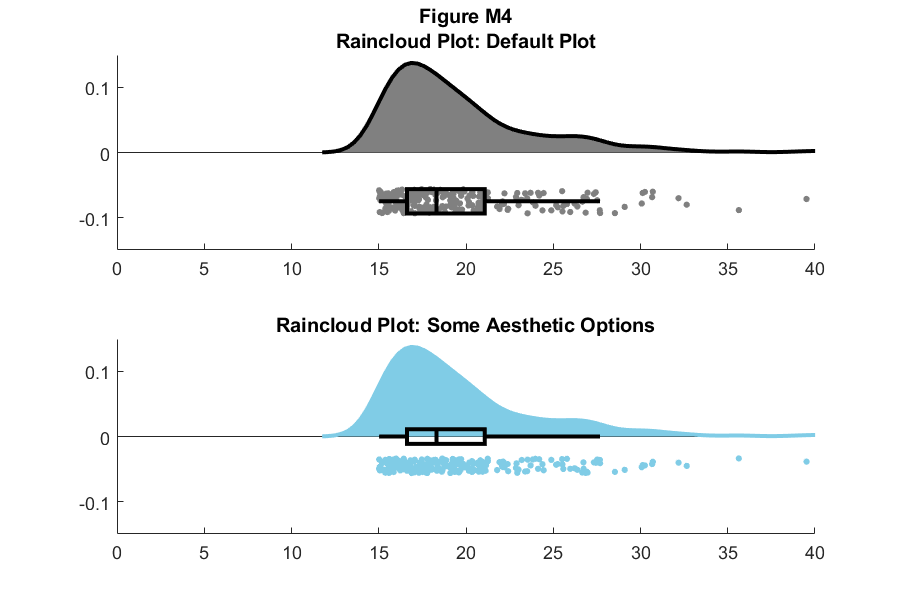

f4 = figure('Position', fig_position);
subplot(2, 1, 1)
h1 = raincloud_plot(d{1}, 'box_on', 1);
title(['Figure M4' newline 'Raincloud Plot: Default Plot']);
set(gca, 'XLim', [0 40]);
box off
subplot(2, 1, 2)
h2 = raincloud_plot(d{1}, 'box_on', 1, 'box_dodge', 1, 'box_dodge_amount',...
0, 'dot_dodge_amount', .3, 'color', cb(1,:), 'cloud_edge_col', cb(1,:));
title('Raincloud Plot: Some Aesthetic Options');
set(gca, 'XLim', [0 40]);
box off

% save
print(f4, fullfile(figdir, '4Rain2.png'), '-dpng');

## The function returns a cell array for various figure parts, so you can also call the base function and then change things with normal 'set' commands, like so:

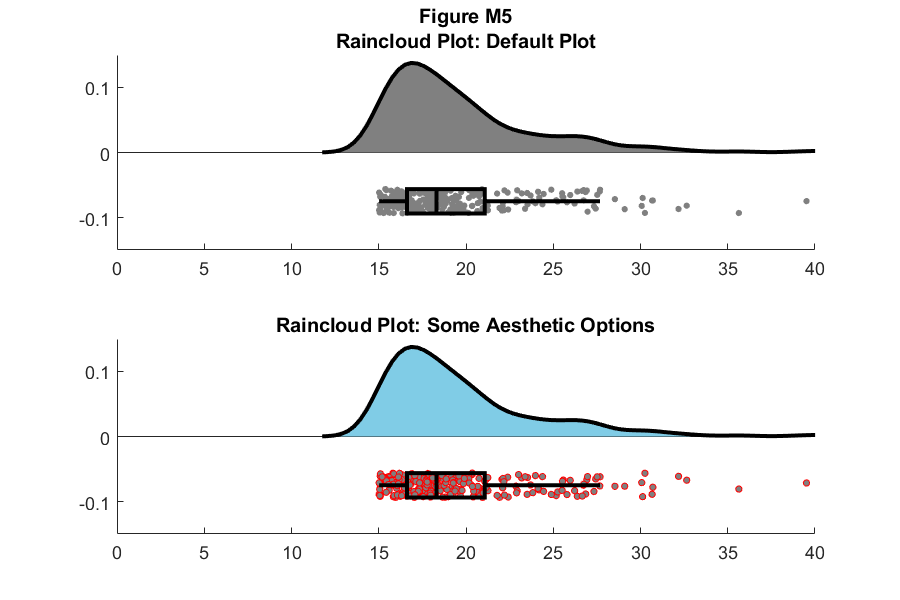

f5 = figure('Position', fig_position);
subplot(2, 1, 1)
h1 = raincloud_plot(d{1}, 'box_on', 1);
title(['Figure M5' newline 'Raincloud Plot: Default Plot']);
set(gca, 'XLim', [0 40]);
box off
subplot(2, 1, 2)
h2 =  raincloud_plot(d{1}, 'box_on', 1);
title('Raincloud Plot: Some Aesthetic Options');
set(h2{1}, 'FaceColor', cb(1, :)); % handles 1-6 are the cloud area, scatterpoints, and boxplot elements respectively
set(h2{2}, 'MarkerEdgeColor', 'red'); % 
set(gca, 'XLim', [0 40]);
box off

% save
print(f5, fullfile(figdir, '5Rain3.png'), '-dpng');

## You can also control the smoothness of the probability density function by calling the 'bandwidth' parameter. Additionally, if you have Cyril Pernet's robust statistics toolbox on your path, you can call the 'rash' function for an alternative kernel density function:

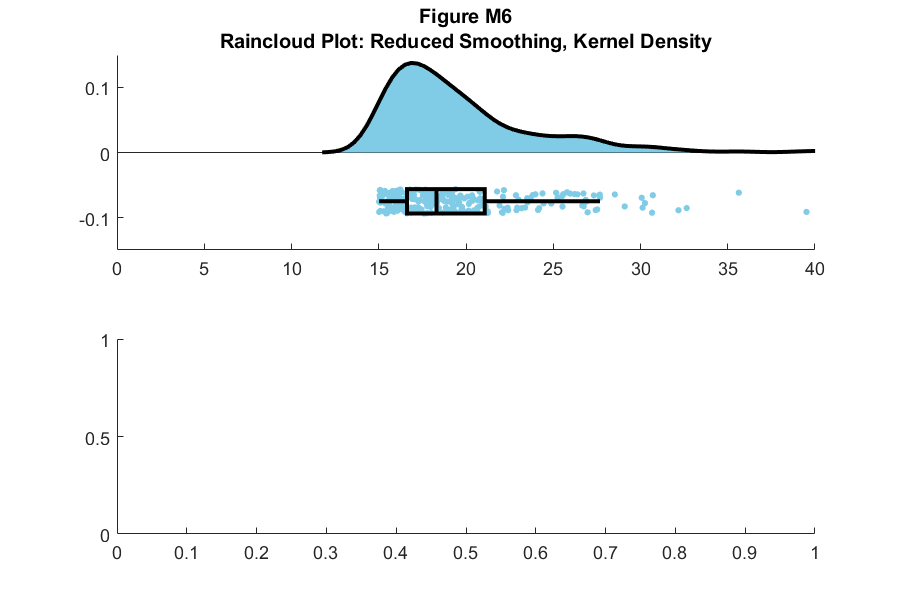

f6 = figure('Position', fig_position);
subplot(2, 1, 1)
h1 = raincloud_plot(d{1}, 'box_on', 1, 'color', cb(1,:), 'bandwidth', .2, 'density_type', 'ks');
title(['Figure M6' newline 'Raincloud Plot: Reduced Smoothing, Kernel Density'])
set(gca, 'XLim', [0 40]);
box off
subplot(2, 1, 2)

% must have: https://github.com/CPernet/Robust_Statistical_Toolbox
h2 = raincloud_plot(d{1}, 'box_on', 1, 'color', cb(2,:), 'bandwidth', 1, 'density_type', 'rash');

Error using raincloud_plot (line 100)
Could not compute density using RASH method. Do you have the Robust Stats toolbox on your path?

title('Raincloud Plot: Rash Density Estimate');
set(gca, 'XLim', [0 40]);
box off

% save
print(f6, fullfile(figdir, '6Rain4.png'), '-dpng');


## Here, we'll use the dot and box dodge options to create an overlapping set of raincloud plots, useful for group comparison. The function can be called repeatedly (e.g., from within a loop) - each iteration will overlay the previous. Note that here we're using the 'alpha' parameter to make the plot area see-through:

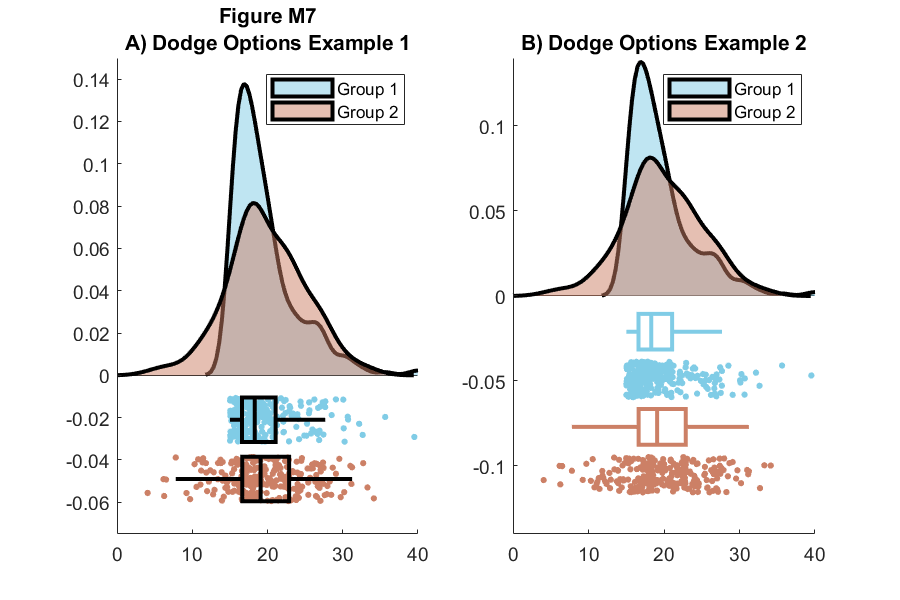

% example 1
f7 = figure('Position', fig_position);
subplot(1, 2, 1)
h1 = raincloud_plot(d{1}, 'box_on', 1, 'color', cb(1,:), 'alpha', 0.5,...
     'box_dodge', 1, 'box_dodge_amount', .15, 'dot_dodge_amount', .15,...
     'box_col_match', 0);
h2 = raincloud_plot(d{2}, 'box_on', 1, 'color', cb(4,:), 'alpha', 0.5,...
     'box_dodge', 1, 'box_dodge_amount', .35, 'dot_dodge_amount', .35, 'box_col_match', 0);
legend([h1{1} h2{1}], {'Group 1', 'Group 2'});
title(['Figure M7' newline 'A) Dodge Options Example 1']);
set(gca,'XLim', [0 40], 'YLim', [-.075 .15]);
box off

% example 2
subplot(1, 2, 2)
h1 = raincloud_plot(d{1}, 'box_on', 1, 'color', cb(1,:), 'alpha', 0.5,...
     'box_dodge', 1, 'box_dodge_amount', .15, 'dot_dodge_amount', .35,...
     'box_col_match', 1);
h2 = raincloud_plot(d{2}, 'box_on', 1, 'color', cb(4,:), 'alpha', 0.5,...
     'box_dodge', 1, 'box_dodge_amount', .55, 'dot_dodge_amount', .75,...
     'box_col_match', 1);
legend([h1{1} h2{1}], {'Group 1', 'Group 2'});
title('B) Dodge Options Example 2');
set(gca,'XLim', [0 40]);
box off

% save
print(f7, fullfile(figdir, '7Rain5.png'), '-dpng');

## You can also control the jitter and position of the 'raindrops' in the Y-plane by calling the figure handles:

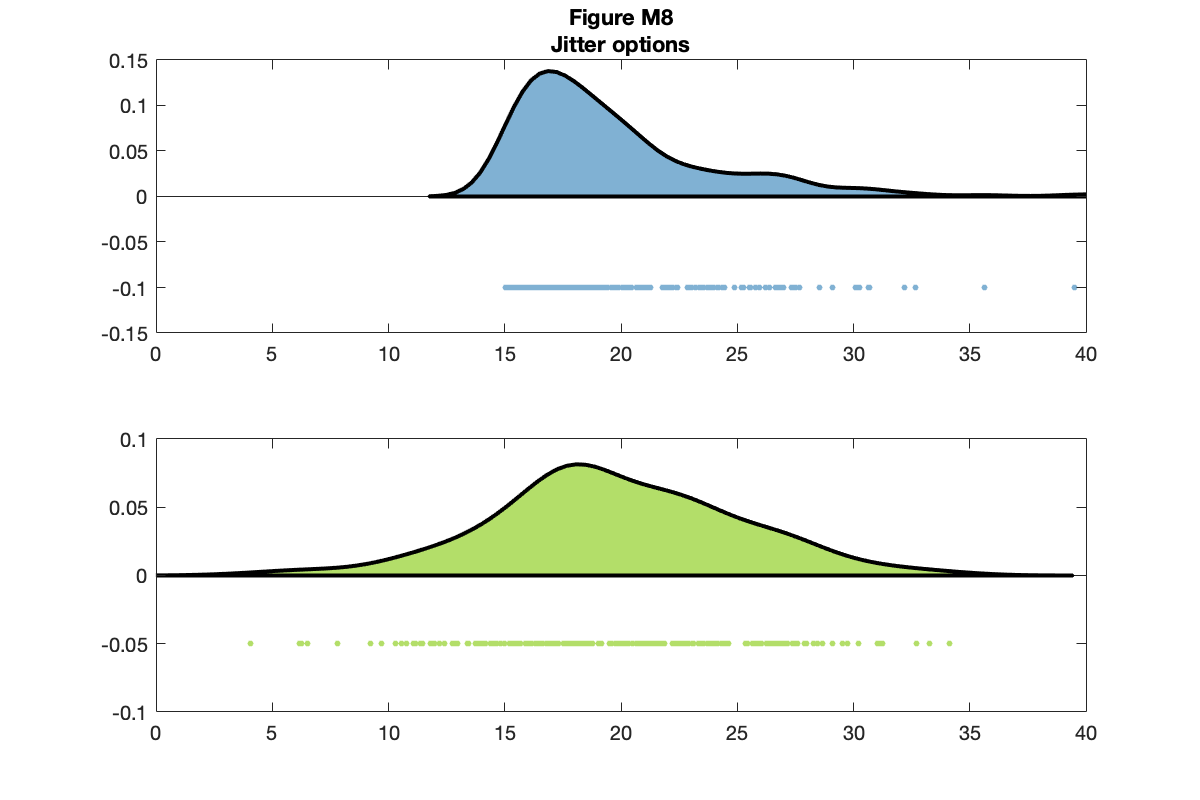

f8 = figure('Position', fig_position);
subplot(2, 1, 1)
h1 = raincloud_plot(d{1}, 'color', cb(5, :));
set(gca, 'XLim', [0 40]);
h1{2}.YData = repmat(-0.1, n, 1);
title(['Figure M8' newline 'Jitter options']);
subplot(2, 1, 2)
h2 = raincloud_plot(d{2}, 'color', cb(7, :));
set(gca, 'XLim', [0 40]);
h2{2}.YData = repmat(-0.05, n, 1); 

% save
print(f8, fullfile(figdir, '8Rain6.png'), '-dpng');

## For the final examples, we'll consider a more complex factorial situation where we have multiple groups and observations. To illustrate this, we'll use a more complex implementation of rainclouds encoded in the 'rm_raincloud.m' function.

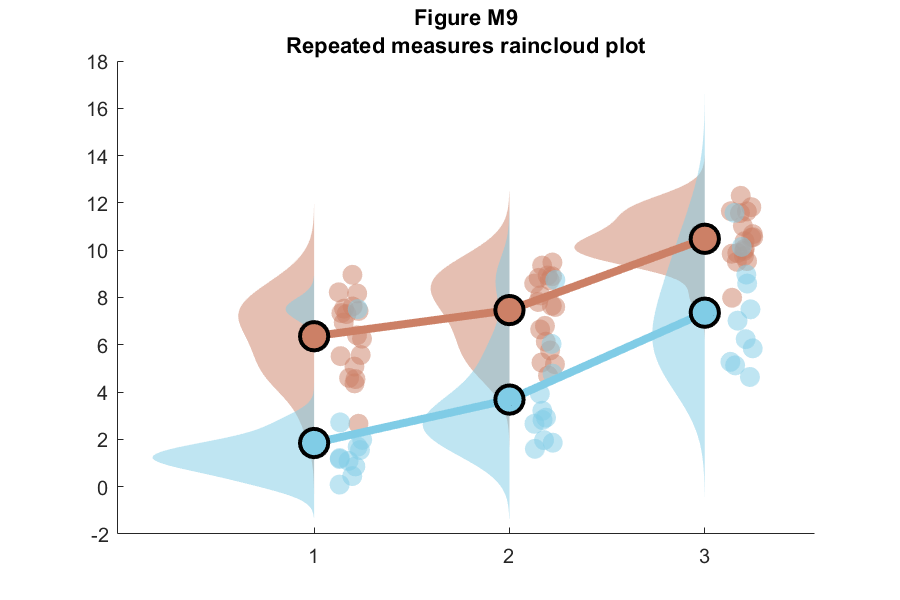

% grab 'repeated_measures_data.csv';
D = dlmread('./repeated_measures_data.csv');

% read into cell array of the appropriate dimensions
for i = 1:3
    for j = 1:2
        data{i, j} = D(D(:, 2) == i & D(:, 3) ==j);
    end
end

% make figure
f9  = figure('Position', fig_position);
h   = rm_raincloud(data, cl);
set(gca, 'YLim', [-0.3 1.6]);
title(['Figure M9' newline 'Repeated measures raincloud plot']);

% save
print(f9, fullfile(figdir, '9RmRain1.png'), '-dpng');

## As above, 'rm_raincloud.m' returns a cell-array of handles to the various figure parts. We can add aesthetic options by calling these handles.

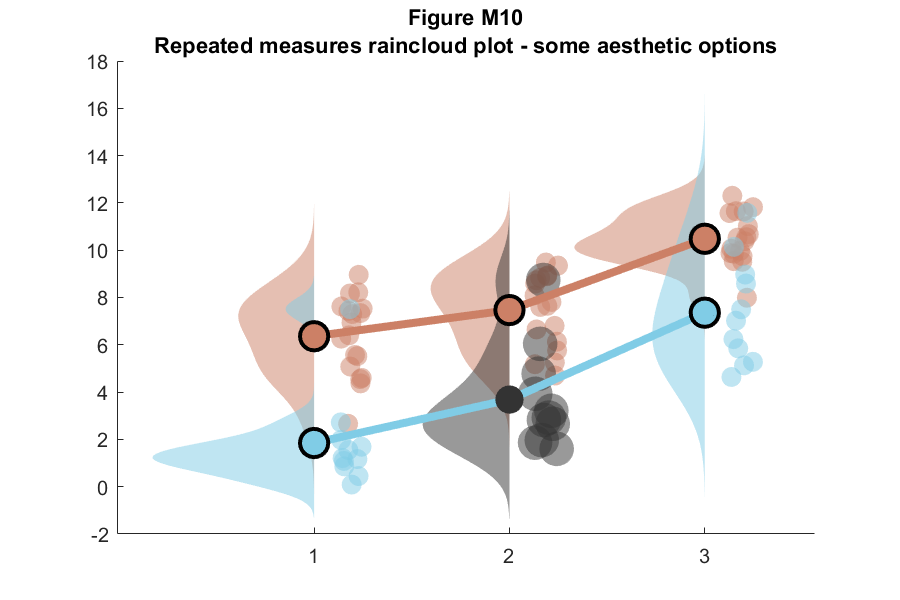

% make figure
f10 = figure('Position', fig_position);
h   = rm_raincloud(data, cl);
set(gca, 'YLim', [-0.3 1.6]);
title(['Figure M10' newline 'Repeated measures raincloud plot - some aesthetic options'])

% define new colour
new_cl = [0.2 0.2 0.2];

% change one subset to new colour and alter dot size
h.p{2, 2}.FaceColor         = new_cl;
h.s{2, 2}.MarkerFaceColor   = new_cl;
h.m(2, 2).MarkerEdgeColor   = 'none';
h.m(2, 2).MarkerFaceColor   = new_cl;
h.s{2, 2}.SizeData          = 300;

% save
print(f10, fullfile(figdir, '10RmRain2.png'), '-dpng');

## That's it! Hopefully this guide has shown you how you can customize your Raincloud plots for a variety of different purposes. This concludes our Matlab tutorial!